# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

-

## Preguntas

- ¿Qué hacer cuando no deja simular 30 horas? (error de step)

- Tengo error muy grande con la exponencial a lazo abierto, es normal?

## Proceso de respiración de *S. cerevisiae *con sistema de cultivo fed-batch


$$\[
\begin{cases} 
\dot{x} = \mu x - Dx \\ 
\dot{s} = -k\mu x + D(s_{in}-s) \\ 
\dot{V} = F_{in}
\end{cases}
\]$$



$$\[
\mu(s) = \mu_{\max} \frac{s}{s + K_s}
\]$$


DatosModeloTP4

sim_hours = 30; % la cantidad de horas que se van a simular
timeStep = 1e-2;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

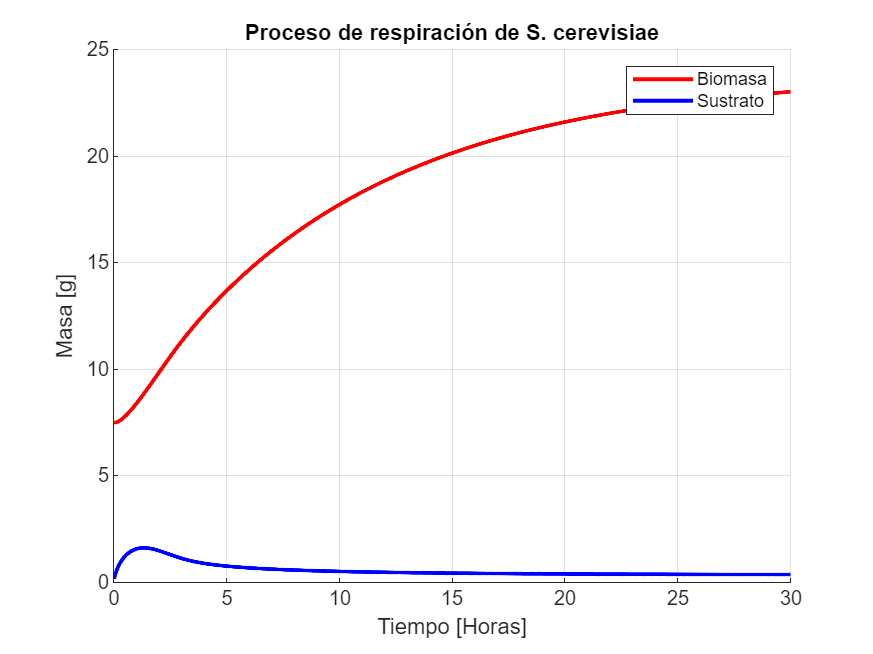

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('TP4', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de respiración de S. cerevisiae');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

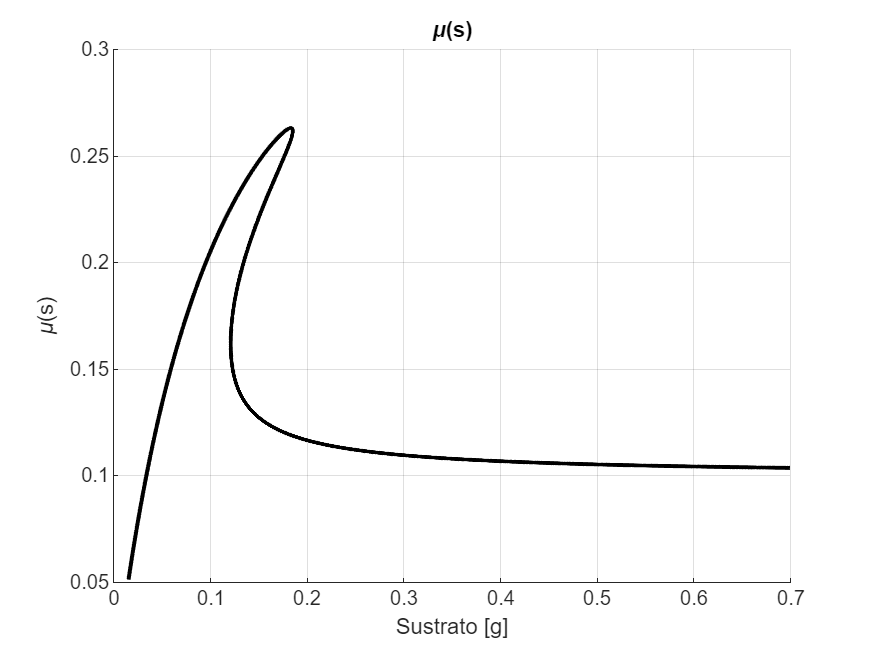


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate.*volume, mu, 'k', 'LineWidth', 2);

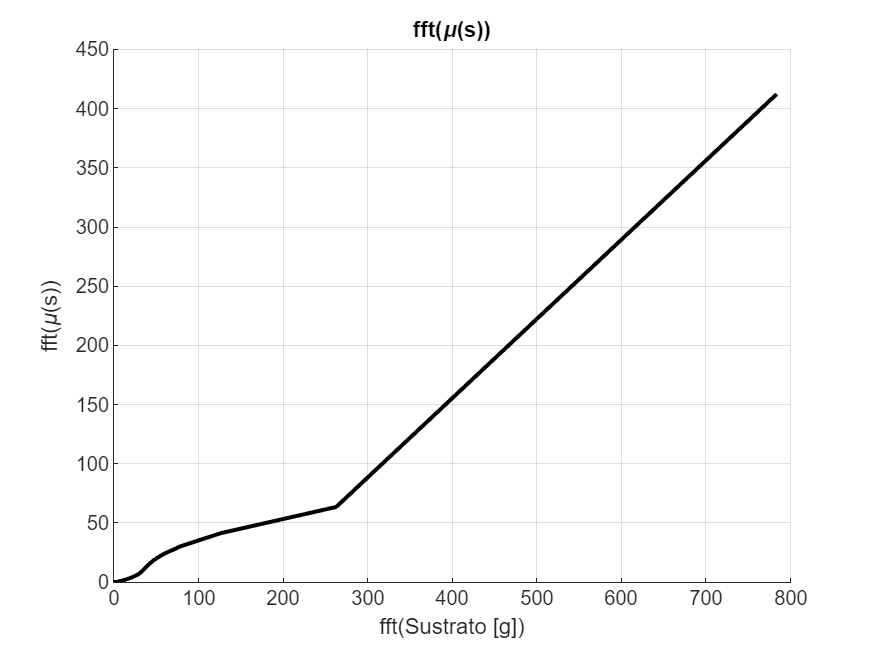


[mu_freq1] = abs(fft(mu));
[s_freq1] = abs(fft(sustrate.*volume));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('fft(\mu(s))');
xlabel('fft(Sustrato [g])');
ylabel('fft(\mu(s))');
plot(s_freq1, mu_freq1, 'k', 'LineWidth', 2);

## Control exponencial a lazo abierto

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.126;
modelParameters.mu_r=mu_r;

params={0};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_x0 = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Resultados

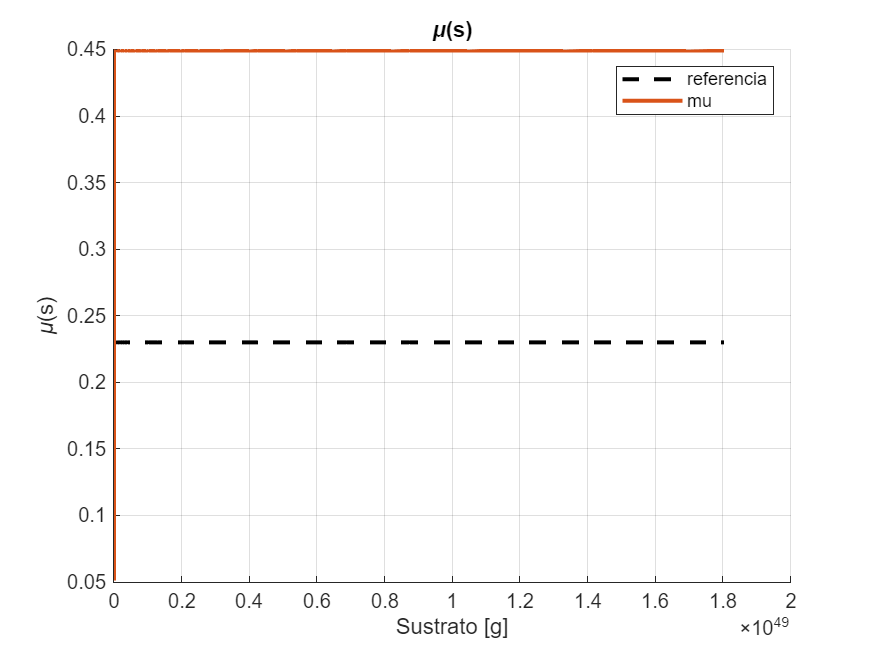

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_x0, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_x0, mus{1}, 'LineWidth', 2);

legend('referencia', 'mu');

Errores relativos

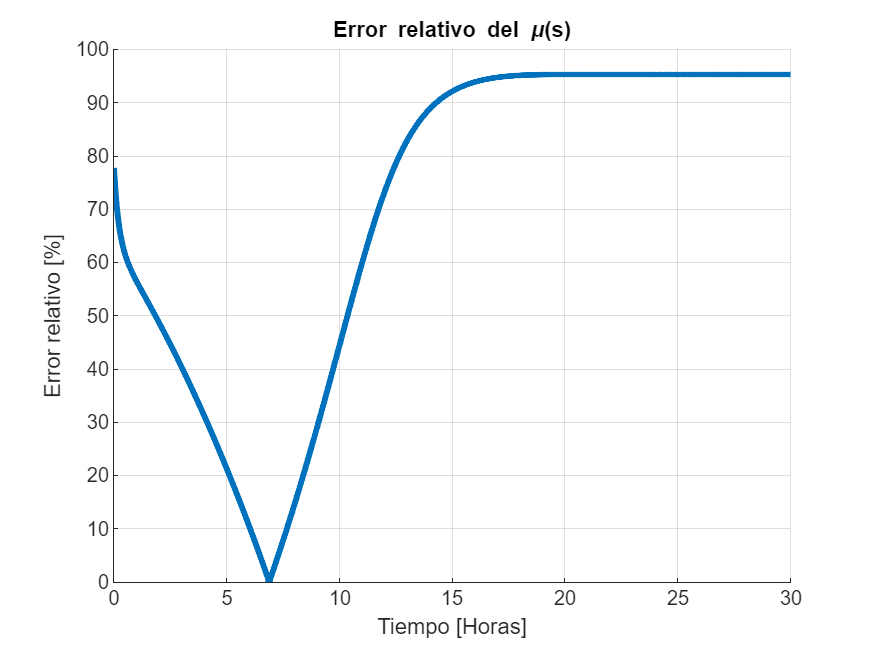

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);

## Variaciones en los parámetros

### Incertidumbre en x0

Controlado con C(s)=Kp y variaciones en las condiciones iniciales:

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.x0=params{i};

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_x0 = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Ahora se muestran los resultados, comparando el caso cuando se tiene variaciones en las condiciones iniciales y como los controadores empleados responden a estas variaciones, es decir su robustez.

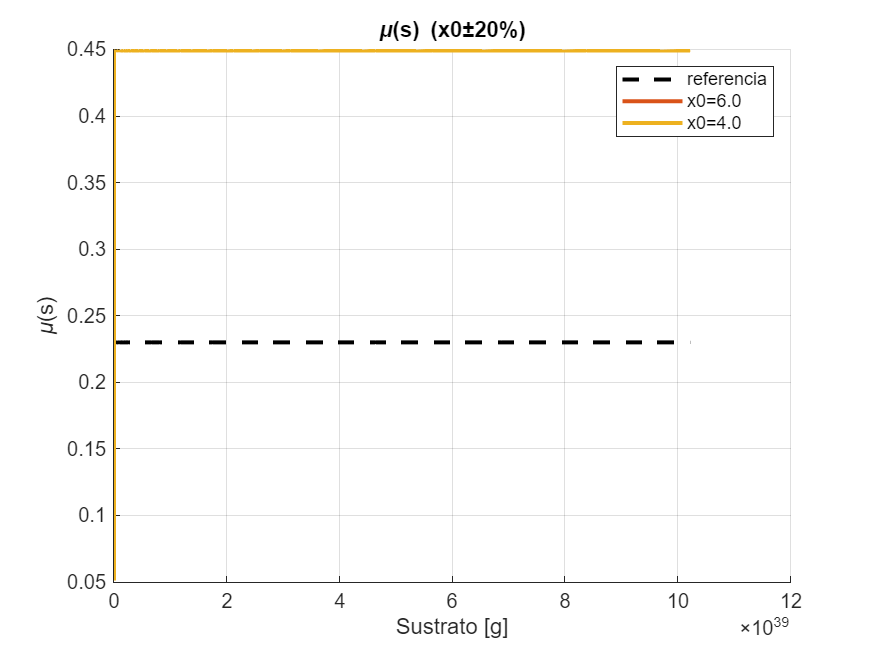

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (x0±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_x0, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_x0, mus{1}, 'LineWidth', 2);
plot(sustrate_x0, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('x0=%.1f', params{1}), ...
    sprintf('x0=%.1f', params{2}));

Errores relativos

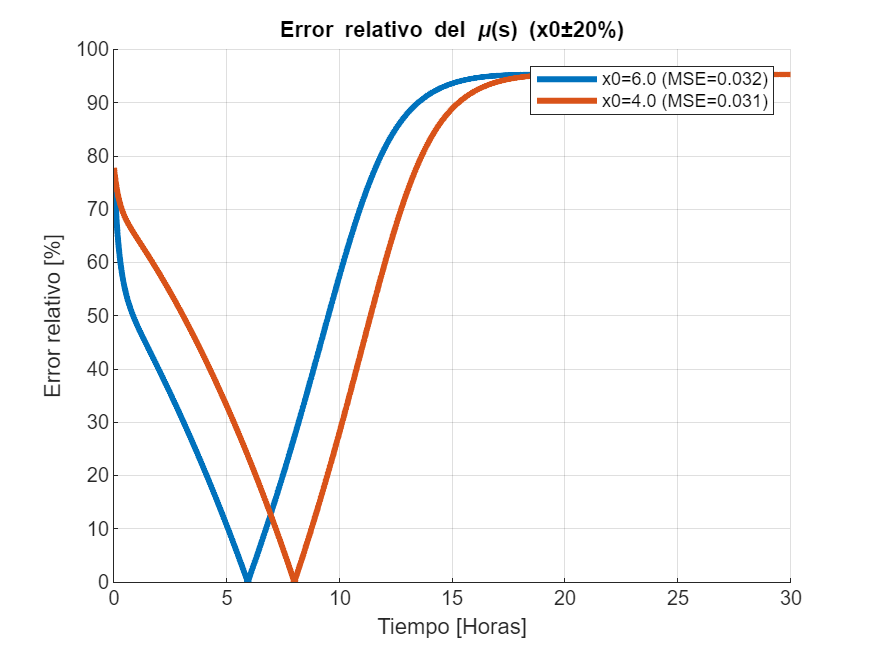

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.3f)', params{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.3f)', params{2}, MSE{2}));

Ambos terminan convergiendo a pesar de tener un error en el valor inicial.

### Incertidumbre en ks 

Ahora hago lo mismo que antes pero variando $k_s$

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_ks={ks*(1.2),ks*(0.8)}; % más/menos 20% del ks
mus_ks=cell(length(params_ks));
error_ks=cell(length(params_ks));
MSE_ks=cell(length(params_ks));
for i=1:length(params_ks)
    modelParameters.K = [1;-params_ks{i}];

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_ks{i}))*mu_r;
 
    error_ks{i}=(mu_r_vector-mus_ks{i});
    MSE_ks{i} = immse(reshape(mu_r_vector, size(mus_ks{i})), mus_ks{i});
end

Ahora se muestran las gráficas

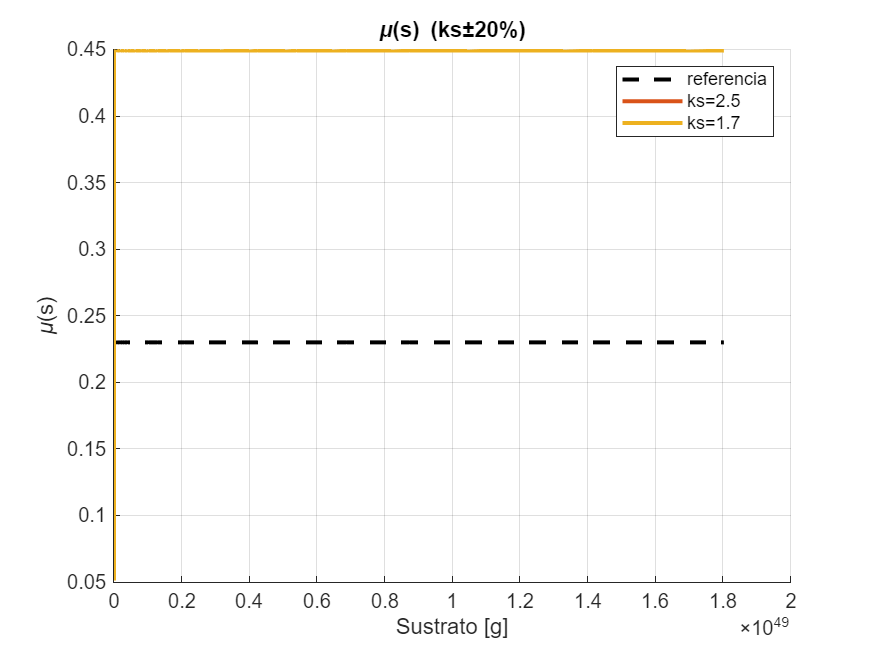

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_ks, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_ks, mus_ks{1}, 'LineWidth', 2);
plot(sustrate_ks, mus_ks{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ks=%.1f', params_ks{1}), ...
    sprintf('ks=%.1f', params_ks{2}));

Y las del error relativo son:

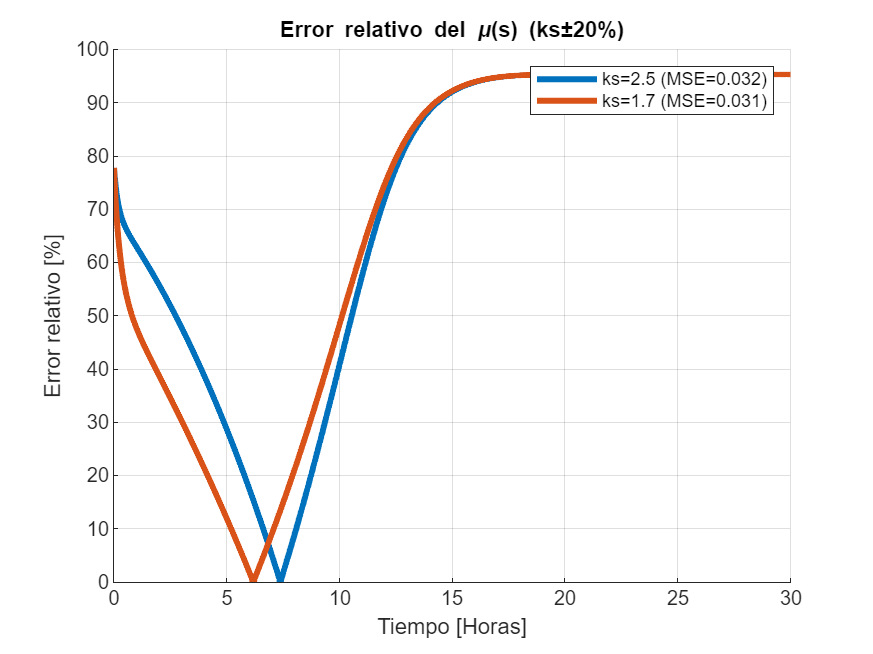

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks=%.1f (MSE=%.3f)', params_ks{1}, MSE_ks{1}), ...
    sprintf('ks=%.1f (MSE=%.3f)', params_ks{2}, MSE_ks{2}));

Viendo los resultados, se podría concluir que es más robusto ante variaciones en $k_s$

### Incertidumbre en Ks

Ahora hago lo mismo que antes pero variando $K_s$

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_Ks={Ks*(1.2),Ks*(0.8)}; % más/menos 20% del ks
mus_Ks=cell(length(params_Ks));
error_Ks=cell(length(params_Ks));
MSE_Ks=cell(length(params_Ks));
for i=1:length(params_Ks)
    modelParameters.mu_model.Ks=Ks;

    sim_out = sim('TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_Ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_Ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_Ks{i}))*mu_r;
 
    error_Ks{i}=(mu_r_vector-mus_Ks{i});
    MSE_Ks{i} = immse(reshape(mu_r_vector, size(mus_Ks{i})), mus_Ks{i});
end

Ahora se muestran las gráficas

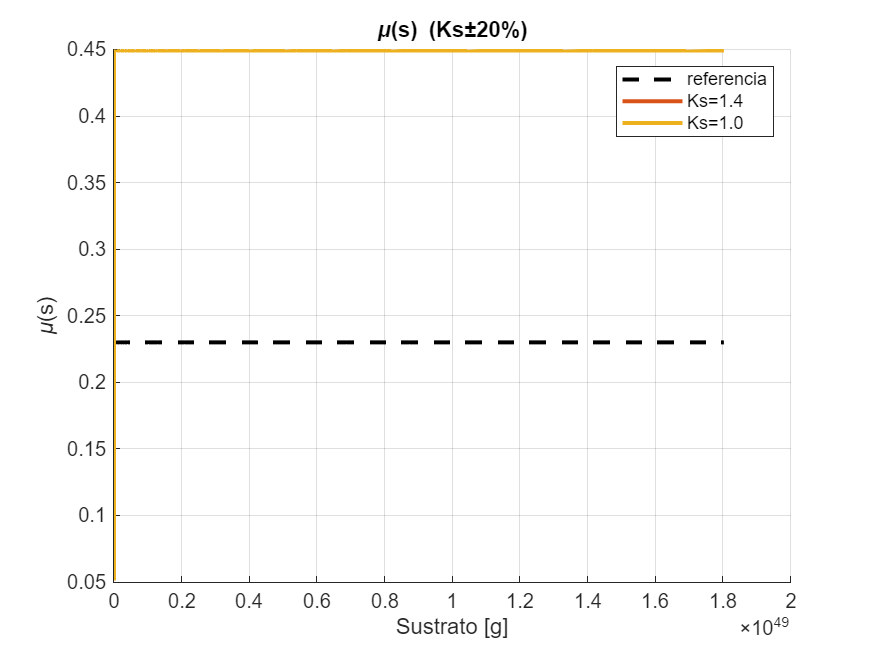

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Ks±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_Ks, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_Ks, mus_Ks{1}, 'LineWidth', 2);
plot(sustrate_Ks, mus_Ks{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('Ks=%.1f', params_Ks{1}), ...
    sprintf('Ks=%.1f', params_Ks{2}));

Y las del error relativo son:

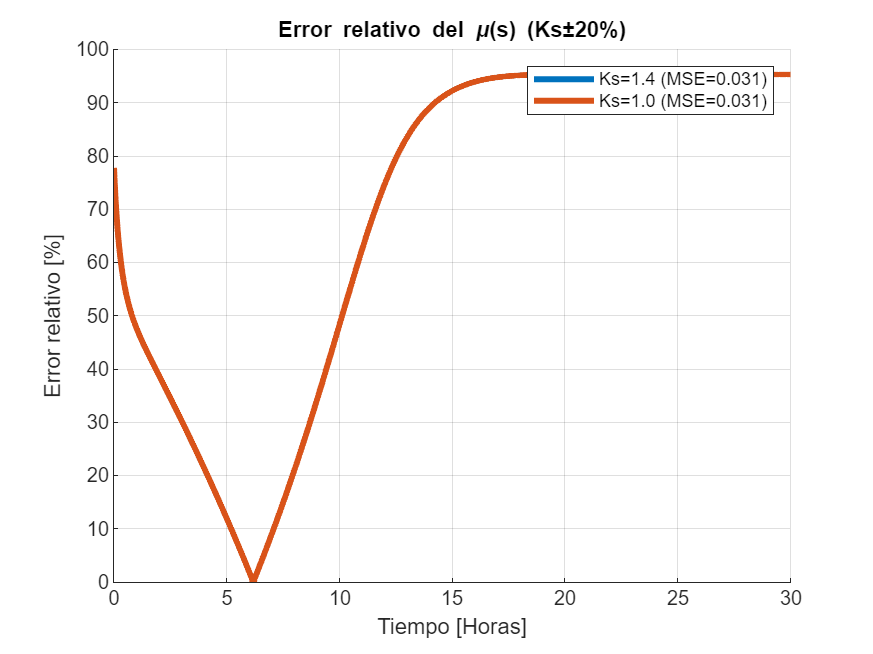

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (Ks±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_Ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_Ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('Ks=%.1f (MSE=%.3f)', params_Ks{1}, MSE_Ks{1}), ...
    sprintf('Ks=%.1f (MSE=%.3f)', params_Ks{2}, MSE_Ks{2}));

Viendo los resultados, se podría concluir que es indiferente a variaciones de $K_s$, por lo que es muy buen control para cuando hay incertidumbre en este parámetro

## Control a lazo cerrado

### Control proporcional al error

Ahora trato de implementar una ley de alimentación exponencial a lazo cerrado

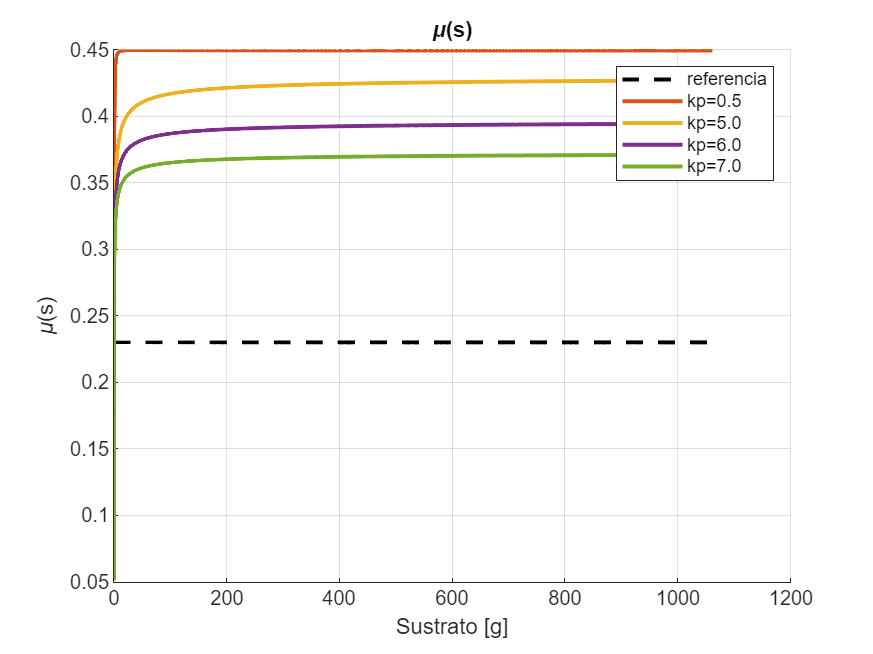

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
% modelParameters.kp=0.1; % factor proporcional

params={0.5,5,6,7};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('TP4_control_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('kp=%.1f', params{1}), ...
    sprintf('kp=%.1f', params{2}), ...
    sprintf('kp=%.1f', params{3}), ...
    sprintf('kp=%.1f', params{4}));

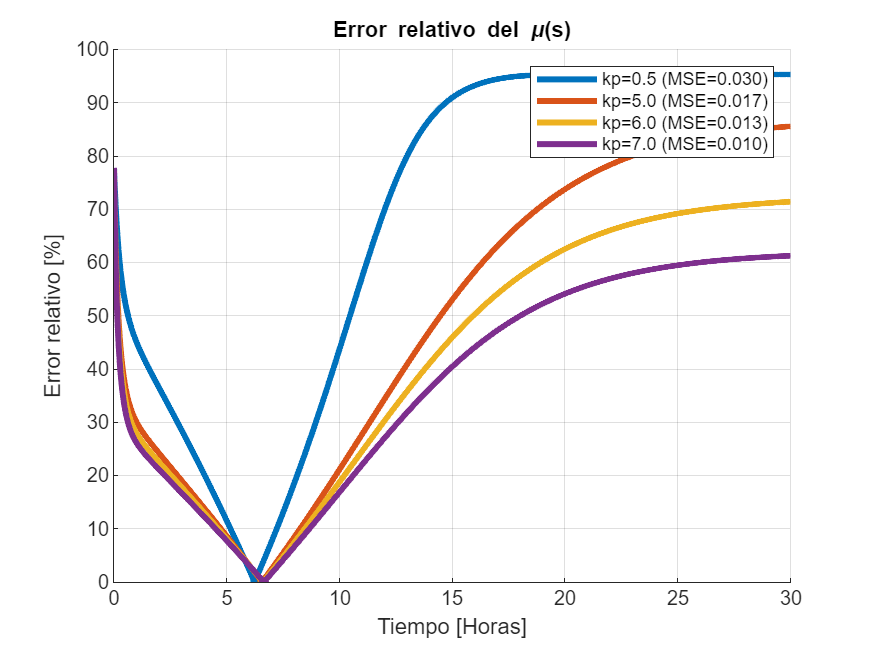


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('kp=%.1f (MSE=%.3f)', params{1}, MSE{1}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{2}, MSE{2}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{3}, MSE{3}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{4}, MSE{4}));

### Proporcional integrativo

Ahora agrego un término integrativo

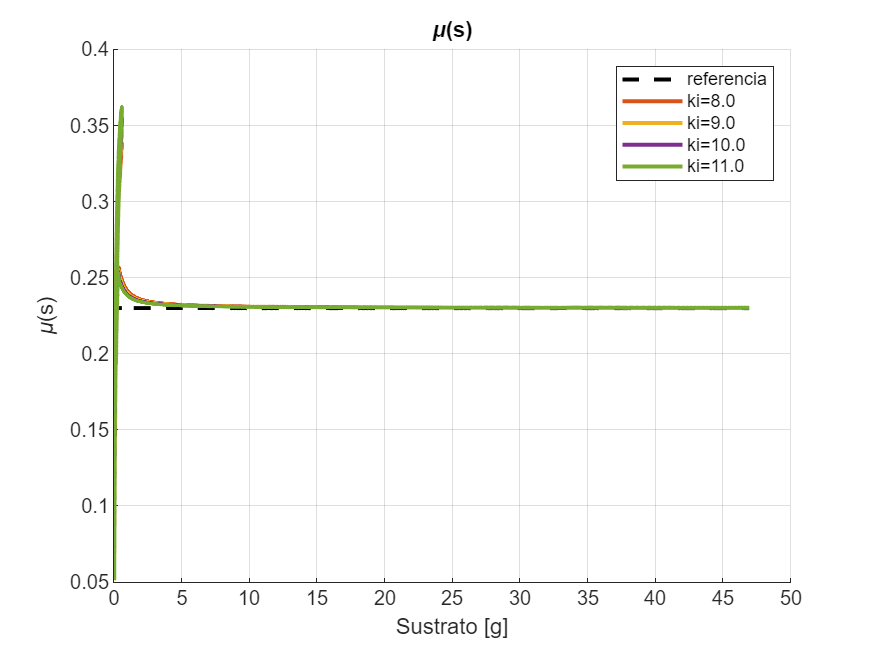

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
% modelParameters.ki=0.1; % factor integrativa
e0=mu_r*1.5;

params={8, 9, 10, 11};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}), ...
    sprintf('ki=%.1f', params{3}), ...
    sprintf('ki=%.1f', params{4}));

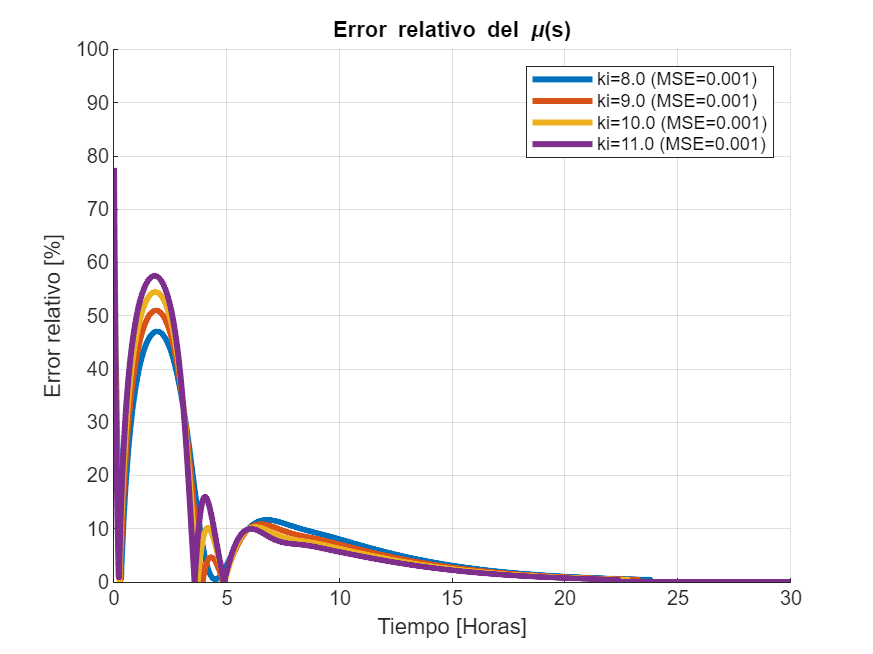


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.3f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{2}, MSE{2}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{3}, MSE{3}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{4}, MSE{4}));